MAX_SAMPLES = 500000;
P_HEADS = 0.25;
P_TAILS = 1 - P_HEADS;

x = geornd(P_HEADS, MAX_SAMPLES, 1) + 1;

x_bar = mean(x)

x_bar = 3.9960

x_var = var(x)

x_var = 11.9323

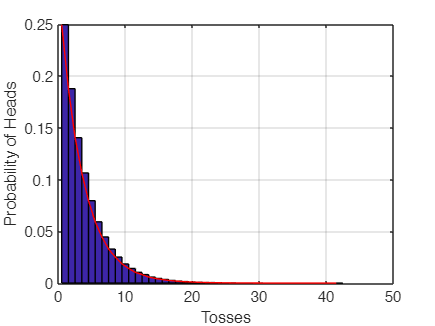


[tosses, edges] = histcounts(x, 'Normalization', 'probability');
figure;
bar(edges(1:end-1), tosses, 'histc');
xlabel('Tosses');
ylabel('Probability of Heads');
grid("on")
hold on;
plot(edges(1:end-1), tosses, '-r');
hold off;


[mu, sigma, muci, sigmaci] = normfit(x);
fprintf('CI: [%.2f, %.2f]\n', muci);

CI: [3.99, 4.01]


%% FP